# CubeSat Mission Analysis with Satellite Scenario

This example shows how to analyze mission geometry calculated during simulation using Aerospace Toolbox™ **Satellite Scenario** tools.

The analysis demonstrates how to:

- Create a satellite scenario using logged satellite position and attitude simulation data.

- Identify access between the onboard sensor and the imaging target.

- Visualize the scenario with **satelliteScenarioViewer.**

## Run the Simulation

Run the simulation if the simulation output object `out` does not exist. 

arch.model = "asbCubeSatArchModel";
if ~exist('out','var')
    open_system(arch.model);
    out = sim(arch.model);
end

Get simulation start date from the `CubeSatProfile.CubeSatEnterprise` stereotype definition in component `asbCubeSatArchModel/CubeSat Mission Enterprise`.

arch.cubeSatModel = systemcomposer.loadModel(arch.model);
mission.startDateJD = eval(getProperty(arch.cubeSatModel.lookup("Path", ...
    "asbCubeSatArchModel/CubeSat Mission Enterprise"), ...
    "CubeSatProfile.CubeSatEnterprise.MissionStartDate"));
mission.startDate = datetime(mission.startDateJD, ConvertFrom="juliandate");

## Extract States from Simulation Output

Extract the logged position, velocity, and attitude data from the simulation output structure.

logged.lla = out.yout{1}.Values.LatLonAlt;
logged.X_ecef = out.yout{1}.Values.X_ecef;
logged.V_ecef = out.yout{1}.Values.V_ecef;
logged.q_ecef2b = out.yout{1}.Values.q_ecef2b;

Set the start time of the **timetable** object to the mission start date.

logged.lla.Properties.StartTime = mission.startDate;
logged.lla = splitvars(logged.lla, "Data", NewVariableNames=["lat", "lon", "alt"]);
disp(head(logged.lla))

            Time             lat        lon         alt    
    ____________________    ______    _______    __________

    01-Jul-2019 11:00:00    5.3932     -27.24    1.6741e+06
    01-Jul-2019 11:00:01    5.4421    -27.256    1.6741e+06
    01-Jul-2019 11:00:02    5.4911    -27.272    1.6741e+06
    01-Jul-2019 11:00:03      5.54    -27.288    1.6741e+06
    01-Jul-2019 11:00:03      5.58    -27.301    1.6741e+06
    01-Jul-2019 11:00:04    5.5889    -27.304    1.6741e+06
    01-Jul-2019 11:00:05    5.6378    -27.319    1.6741e+06
    01-Jul-2019 11:00:06    5.6868    -27.335    1.6741e+06



## Polulate the Satellite Scenario Object

Use **satelliteScenario** to create a new scenario. 

scenario = satelliteScenario(mission.startDate, mission.startDate + hours(4), 10);

Add a ground station to the scenario located at MathWorks in Natick.  This is the imaging target for the onboard sensor.

gs = groundStation(scenario, 42.2775, -71.2468, Name="GroundStation");

Add a satellite to the scenario from saved position and velocity **timetable** data.

sat = satellite(scenario, logged.X_ecef, logged.V_ecef, CoordinateFrame="ecef", Name="CubeSat");

Orient the satellite using the saved attitude data from the model.

pointAt(sat, logged.q_ecef2b, CoordinateFrame="ecef", ExtrapolationMethod="nadir", Format="quaternion");

Attach a camera to the satellite.  Enable field of view visualization.

sensor = conicalSensor(sat, MaxViewAngle=6);
fieldOfView(sensor);

## Analyze access between camera and target

Perform access analysis between the sensor and ground station.

acc = access(sensor, gs);

Display intervals during which the camera has visibility to the imaging target during the simulation.

accTable = accessIntervals(acc);
display(accTable);

accTable = 2×8 table
          Source              Target         IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    __________________    _______________    ______________    ____________________    ____________________    ________    __________    ________

    "Conical sensor 3"    "GroundStation"          1           01-Jul-2019 11:13:20    01-Jul-2019 11:13:50       30          NaN          NaN   
    "Conical sensor 3"    "GroundStation"          2           01-Jul-2019 13:12:00    01-Jul-2019 13:12:10       10          NaN          NaN   


### View scenario in Satellite Scenario Viewer

Open the Satellite Scenario Viewer to animate the scenario.

satelliteScenarioViewer(scenario);

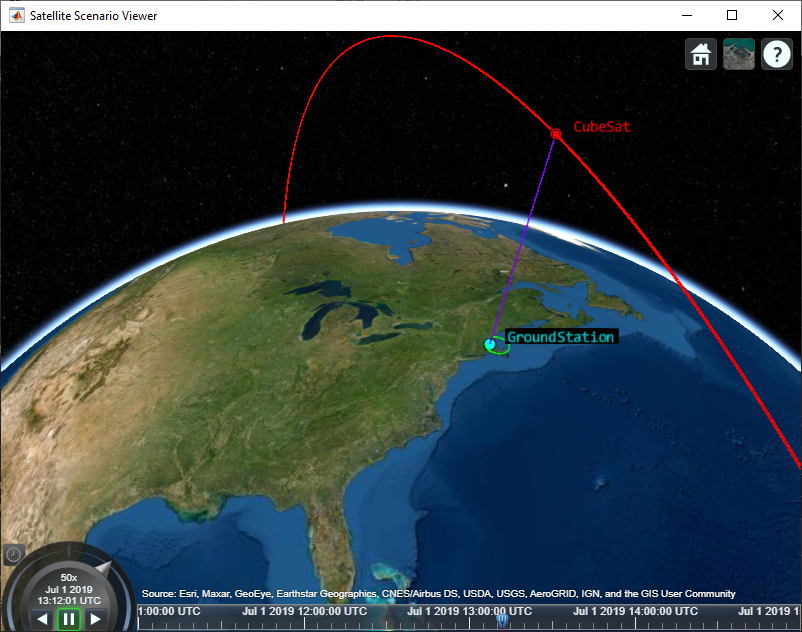

*Copyright 2021 The MathWorks, Inc.*